clear
clc

Create internal variables

Jx = 2;
Jy = 2;
Jz = 4;
m = 4;
g = 9.81;

## Trajectory

we want to go throught points

- [0, 0, 0]

- [1, 5, 1]

- [0, 5, 2]

- [10, 3, 3]

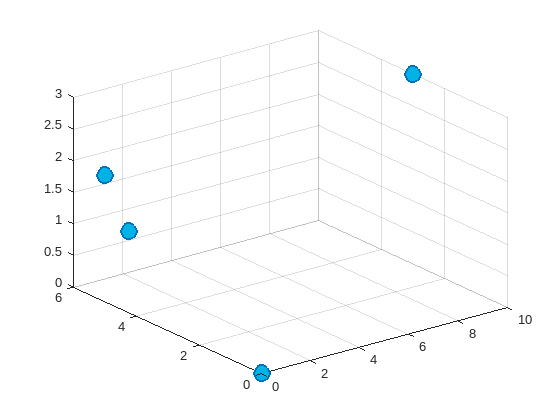

Xp = [0 1 0 10];
Yp = [0 5 5 3];
Zp = [0 1 2 3];
Pp = [0 pi/2 pi 3*pi/2];

W = reshape([Xp, Yp, Zp, Pp], 4, []);

% Xp = randi(10, 1, 10);
% Yp = randi(10, 1, 10);
% Zp = randi(10, 1, 10);

figure(1)
plot3(Xp, Yp, Zp, 'o',...
    'LineWidth',2,...
    'MarkerSize',12,...
    'MarkerFaceColor',[0,0.7,0.9])
grid on

## Create trajectory polynomials

we have 4 waypoints, thus the structure will be


$$X=\;\left\lbrack w_1 ,\;w_2 ,\;w_2 ,\;w_3 ,\;w_3 ,\;w_4 ,\;v_{12-23} ,\;v_{23-34} ,\;a_{12-23} ,\;a_{23-34} ,\;v_0 ,v_T \right\rbrack$$


More generally


$$X=\;\left\lbrack w_1 ,\;\ldotp \ldotp \ldotp ,w_n ,v_{12} ,\;\ldotp \ldotp \ldotp ,v_{n-1,n} ,a_{12} ,\;\ldotp \ldotp \ldotp ,a_{n-1,n} ,v_0 ,v_T \right\rbrack$$



$${\backslash \mathrm{#w}}_i \Rightarrow 2n-2$$



$${\backslash \mathrm{#v}}_i \Rightarrow \left\lfloor \frac{{\mathrm{#w}}_i +1}{2}\right\rfloor$$



$${\backslash \mathrm{#a}}_i \Rightarrow {\backslash \mathrm{#v}}_i$$


#### Total size:


$$\backslash \mathrm{#X}=2n-2+2\left(\frac{2n-2}{2}-1\right)+2=4n-4$$


Where $w_n$ denotes the waypoint in appropriate axis, $v_{\textrm{mn}-\textrm{op}}$ is the difference in velocities while transfering between the trajectories, $a_{\textrm{mn}-\textrm{op}}$ is the acceleration in the point of transfer and $v_x$ is the starting and ending velocity.

%    W              v01-12 v12-23 a01-12 a12-23 v0 vT
X = waypoints(Xp)';
Y = waypoints(Yp)';
Z = waypoints(Zp)';
P = waypoints(Pp)';

#### Generate the B matrix

B = generate_B(size(Xp, 2))

B =      1     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     1     2     4     8     0     0     0     0
     0     0     0     0     0     0     0     0     1     2     4     8
     0     0     0     0     0     0     0     0     1     3     9    27
     0     1     2     3     0    -1    -2    -3     0     0     0     0
     0     0     0     0     0     1     4    12     0    -1    -4   -12
     0     0     2     6     0     0    -2    -6     0     0     0     0
     0     0     0     0     0     0     2    12     0     0    -2   -12


#### Generate the trajectories

alpha_X = (B \ X);
alpha_Y = (B \ Y);
alpha_Z = (B \ Z);
alpha_P = (B \ P);

alpha_X = reshape(alpha_X, [4, size(X,1)/4])'

alpha_X =          0         0    4.8000   -3.8000
  -11.2000   33.6000  -28.8000    7.4000
  150.4000 -208.8000   92.4000  -12.8000


alpha_Y = reshape(alpha_Y, [4, size(X,1)/4])'

alpha_Y =          0    0.0000   10.6000   -5.6000
   -7.4000   22.2000  -11.6000    1.8000
   -4.2000   17.4000   -9.2000    1.4000


alpha_Z = reshape(alpha_Z, [4, size(X,1)/4])'

alpha_Z =          0    0.0000    1.8000   -0.8000
   -1.2000    3.6000   -1.8000    0.4000
    8.4000  -10.8000    5.4000   -0.8000


alpha_P = reshape(alpha_P, [4, size(X,1)/4])'

alpha_P =          0    0.0000    2.8274   -1.2566
   -1.8850    5.6549   -2.8274    0.6283
   13.1947  -16.9646    8.4823   -1.2566


#### Plot the generated trajectory

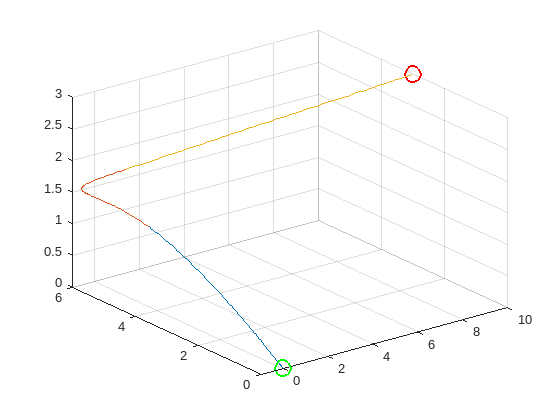

figure(2)

for i = 0:size(Xp, 2)-2
    [x,y,z] = gen_xyz(i, i+1, i+1, alpha_X, alpha_Y, alpha_Z);
    plot3(x, y, z);
    grid on;
    hold on;
end

plot3(Xp(1), Yp(1), Zp(1), 'o',...
    'LineWidth',2,...
    'MarkerSize',12,...
    'Color', 'g')

plot3(Xp(end), Yp(end), Zp(end), 'o',...
    'LineWidth',2,...
    'MarkerSize',12,...
    'Color', 'r')

grid on;
hold off;

function B = generate_B(n)
    syms t
    b = [1, t, t^2, t^3];
    b_d = diff(b, t);
    b_dd = diff(b_d, t);

    num_segments = n - 1;
    total_cols = num_segments * 4;
    segment_1 = 2*n-2;
    total_lines = 4*n - 4;
    B = zeros(total_lines, total_cols);

    row_idx = 1;

    % 1. Position constraints at segment start and end
    for i = 1:num_segments
        B(row_idx, (i-1)*4 + (1:4)) = double(subs(b, t, i-1));
        B(row_idx+1, (i-1)*4 + (1:4))   = double(subs(b, t, i));
        row_idx = row_idx + 2;
    end

    % 2. Velocity continuity at internal waypoints
    for i = 1:segment_1/2 - 1
        B(row_idx, (i-1)*4 + (1:4)) = double(subs(b_d, t, i));
        B(row_idx, (i)*4 + (1:4)) = -double(subs(b_d, t, i));
        row_idx = row_idx + 1;
    end

    % 3. Acceleration continuity at internal waypoints
    for i = 1:segment_1/2 - 1
        B(row_idx, (i-1)*4 + (1:4)) = double(subs(b_dd, t, i));
        B(row_idx, (i)*4 + (1:4)) = -double(subs(b_dd, t, i));
        row_idx = row_idx + 1;
    end

    % 4. Initial velocity constraint
    B(row_idx, 1:4) = double(subs(b_d, t, 0));

    % 5. Final velocity constraint
    B(end, end-3:end) = double(subs(b_d, t, n-1));
end

function W = waypoints(w)
    n = size(w,2);

    W = zeros(1, 2*n-2);
    p = zeros(1, 2*n-2);
    W(1) = w(1);
    tmp_i = 2;

    for i = 2:n-1
        W(tmp_i) = w(i);
        W(tmp_i+1) = w(i);
        tmp_i = tmp_i + 2;
    end

    W(end) = w(end);
    W = [W, p];
end

function [x,y,z] = gen_xyz(s, e, j, ax, ay, az)
    x = zeros(1,100);
    y = zeros(1,100);
    z = zeros(1,100);
    idx = 1;

    for i=linspace(s, e)
        x(idx) = ax(j, 1) + ax(j, 2)*i + ax(j, 3)*i^2+ ax(j, 4)*i^3;
        y(idx) = ay(j, 1) + ay(j, 2)*i + ay(j, 3)*i^2+ ay(j, 4)*i^3;
        z(idx) = az(j, 1) + az(j, 2)*i + az(j, 3)*i^2+ az(j, 4)*i^3;
        idx = idx+1;
    end
end